## Preparación del modelo en simulink

clear all;clc

model='especies';
ParIn={'x0','y0','a','b','c','d','m','n'};
Ranges=[0.3347 0.5021; 0.5052 0.7578; 0.2069 0.3103; 0.0162 0.0244; 0.0459 0.0689; 0.0078 0.0117; 0.0457 0.0685; 0.0038 0.0058];
out_names = {'x','y'};
T = gsua_dataprep(model,Ranges,ParIn,'out_names',out_names)

Setting environment to work with simulink
Setting nominal values
All done!


T = 8×2 table
               Range          Nominal
          ________________    _______

    x0    0.3347    0.5021     0.4184
    y0    0.5052    0.7578     0.6315
    a     0.2069    0.3103     0.2586
    b     0.0162    0.0244     0.0203
    c     0.0459    0.0689     0.0574
    d     0.0078    0.0117    0.00975
    m     0.0457    0.0685     0.0571
    n     0.0038    0.0058     0.0048


## Preparación del modelo en matemática simbólica

clear all;clc

syms x(t) y(t) a b c d m n u(t)
u(t)=0; 
ode1=diff(x)==x*(a-b*x-m*y)+u;
ode2=diff(y)==y*(c-d*y-n*x);
odes=[ode1;ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=-x\left(t\right)\,\left(b\,x\left(t\right)-a+m\,y\left(t\right)\right)\\ \frac{\partial }{\partial t}y\left(t\right)=-y\left(t\right)\,\left(d\,y\left(t\right)-c+n\,x\left(t\right)\right) \end{array}\right)$$

vars = [x y];
domain = [0 50];
modelName = 'esp';
gsua_dataprep(odes,vars,domain,modelName);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccc} x\left(t\right) & y\left(t\right) & a & b & c & d & m & n \end{array}\right)$$

Ranges=[0.3347 0.5021; 0.5052 0.7578; 0.2069 0.3103; 0.0162 0.0244; 0.0459 0.0689; 0.0078 0.0117; 0.0457 0.0685; 0.0038 0.0058];
[T,solver] = gsua_dataprep(odes,vars,domain,modelName,'range',Ranges)

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccc} x\left(t\right) & y\left(t\right) & a & b & c & d & m & n \end{array}\right)$$

T = 8×2 table
               Range          Nominal
          ________________    _______

    x0    0.3347    0.5021     0.4184
    y0    0.5052    0.7578     0.6315
    a     0.2069    0.3103     0.2586
    b     0.0162    0.0244     0.0203
    c     0.0459    0.0689     0.0574
    d     0.0078    0.0117    0.00975
    m     0.0457    0.0685     0.0571
    n     0.0038    0.0058     0.0048


solver = function_handle with value:
    @(init,pars)ode45(@(t,Y)odefun(t,Y,pars),domain,[Table.Range(fixvars,1)',init],opt)


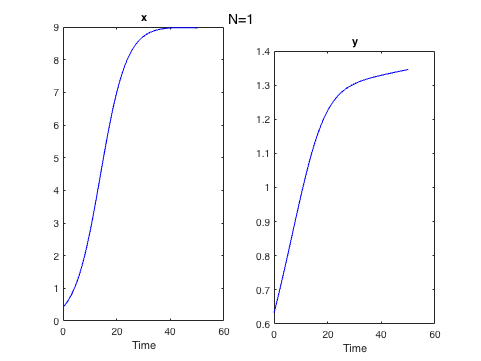

y = gsua_eval(T.Nominal,T);

y(:,end)

ans =     8.9701
    1.3459


## Análisis de incertidumbre

Generating xdata and ynom values
Progress: 100%
Estimated processing time (h:m:s): 0:0:13
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:13
Estimated stop time (h:m:s): 10:3:39
Number of simulations: 100


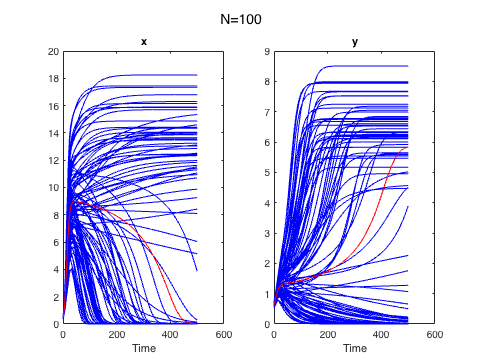

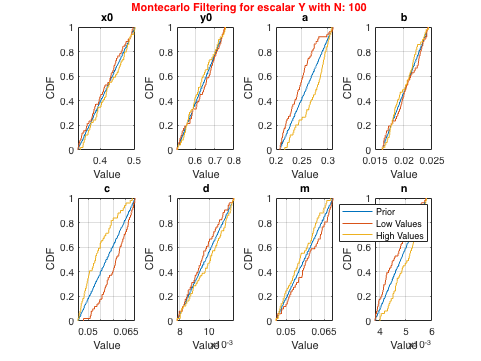

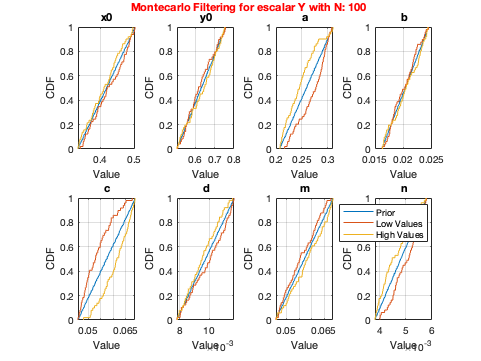

M=gsua_dmatrix(T,100);
Y=gsua_ua(M,T,'parallel',false);